# Project MSB1015: Ayahuasca

## Script 3: Data visualization

## Guus Wilmink, i6156211

## **Load data**

clear all; close all;

% Add Fieldtrip toolbox
addpath('./fieldtrip-20220912');

% Load the data
load('.\processed_1_30Hz.mat');
load('.\processed_30_100Hz.mat');
elec = load(".\freqs_1-30Hz.mat").data_all_mean.elec;

% Specify bands
delta=2.5; theta=6; alpha=10.5; beta=21.5; slowgamma=40; fastgamma=75;

## **Visualize data**

**Select frequency band to visualize in next chunks**

band = 40;

% Prepare data according to band selection
if ismember(band, [delta theta alpha beta])
    dat = processed_1_30Hz;
    if band == delta
        for trial = 1:6
            dat{trial}.powspctrm_b = squeeze(dat{trial}.powspctrm_b(:,:,1));
            dat{trial}.freq        = delta;
        end
    end
    if band == theta
        for trial = 1:6
            dat{trial}.powspctrm_b = squeeze(dat{trial}.powspctrm_b(:,:,2));
            dat{trial}.freq        = theta;
        end
    end
    if band == alpha
        for trial = 1:6
            dat{trial}.powspctrm_b = squeeze(dat{trial}.powspctrm_b(:,:,3));
            dat{trial}.freq        = alpha;
        end
    end
    if band == beta
        for trial = 1:6
            dat{trial}.powspctrm_b = squeeze(dat{trial}.powspctrm_b(:,:,4));
            dat{trial}.freq        = beta;
        end
    end
else
    dat = processed_30_100Hz;
     if band == slowgamma
        for trial = 1:6
            dat{trial}.powspctrm_b = squeeze(dat{trial}.powspctrm_b(:,:,1));
            dat{trial}.freq        = slowgamma;
        end
    end
    if band == fastgamma
        for trial = 1:6
            dat{trial}.powspctrm_b = squeeze(dat{trial}.powspctrm_b(:,:,2));
            dat{trial}.freq        = fastgamma;
        end
    end
end

**Visualize the TFRs plotted onto a 2D model for each trial**

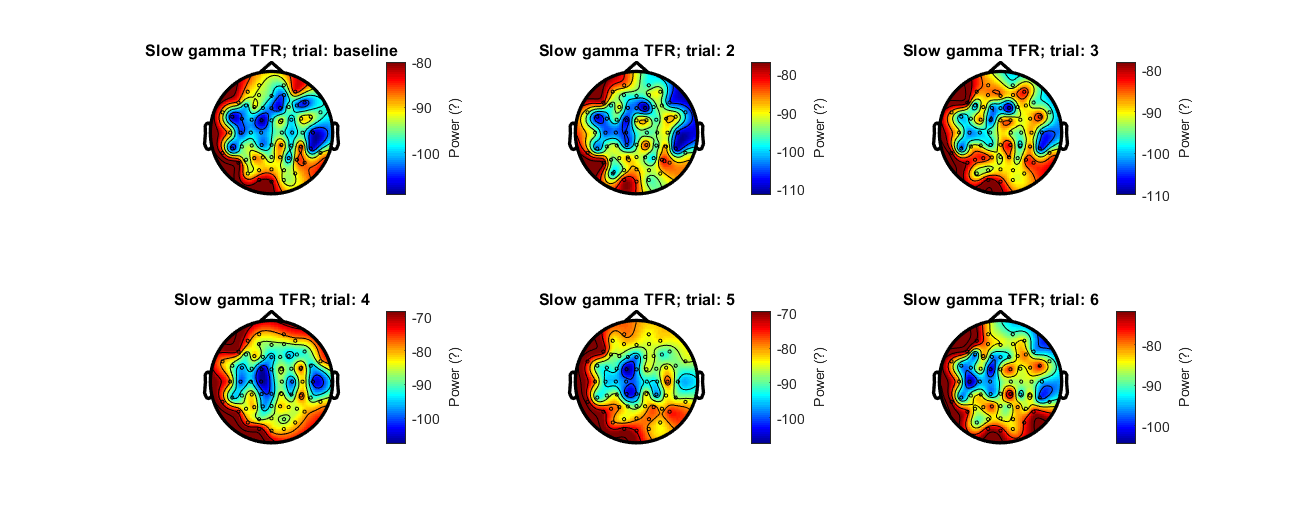

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

creating layout from cfg.elec
creating layout for eeg1010 system


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotER" took 1 seconds
creating layout from cfg.elec
creating layout for eeg1010 system


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotER" took 1 seconds
creating layout from cfg.elec
creating layout for eeg1010 system


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotER" took 0 seconds
creating layout from cfg.elec
creating layout for eeg1010 system


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotER" took 0 seconds
creating layout from cfg.elec
creating layout for eeg1010 system


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotER" took 1 seconds
creating layout from cfg.elec
creating layout for eeg1010 system


the call to "ft_prepare_layout" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotER" took 0 seconds


% Set lower and upper power limits for plotting
if band == delta || band == theta || band == alpha
    lower = -16;
    upper = 1;
end
if band == beta
    lower = -65;
    upper = -35;
end
if band == slowgamma
    lower = -110;
    upper = -60;
end
if band == fastgamma
    lower = -240;
    upper = -180;
end
% Configuration
cfg = [];
cfg.elec      = elec; % Set electrode layout
cfg.parameter = 'powspctrm_b'; % Set banded power spectrum to plot
cfg.colormap  = 'jet'; % Set color map
%cfg.zlim      = [lower upper]; % Set power limits for color gradient
cfg.comment   = 'no'; % Switch off unnecessary annotations
fig1          = figure('position',[680 240 1039 420]); % Create new figure
cfg.figure    = fig1; % Specify figure to plot in

% Plotting
for trial = 1:6
    subplot(2,3,trial)
    ft_topoplotER(cfg, dat{trial})
    h = colorbar;
    set(get(h,'label'),'string','Power (?)');
    if band == delta
        if trial == 1
            title('Delta TFR; trial: baseline')
        else
            title(['Delta TFR; trial: ' num2str(trial)])
        end
    end
    if band == theta
        if trial == 1
            title('Theta TFR; trial: baseline')
        else
            title(['Theta TFR; trial: ' num2str(trial)])
        end
    end
    if band == alpha
        if trial == 1
            title('Alpha TFR; trial: baseline')
        else
            title(['Alpha TFR; trial: ' num2str(trial)])
        end
    end
    if band == beta
        if trial == 1
            title('Beta TFR; trial: baseline')
        else
            title(['Beta TFR; trial: ' num2str(trial)])
        end
    end
    if band == slowgamma
        if trial == 1
            title('Slow gamma TFR; trial: baseline')
        else
            title(['Slow gamma TFR; trial: ' num2str(trial)])
        end
    end
    if band == fastgamma
        if trial == 1
            title('Fast gamma TFR; trial: baseline')
        else
            title(['Fast gamma TFR; trial: ' num2str(trial)])
        end
    end
end

**Visualize power-frequency relations (spectra averaged across subjects and channels)**

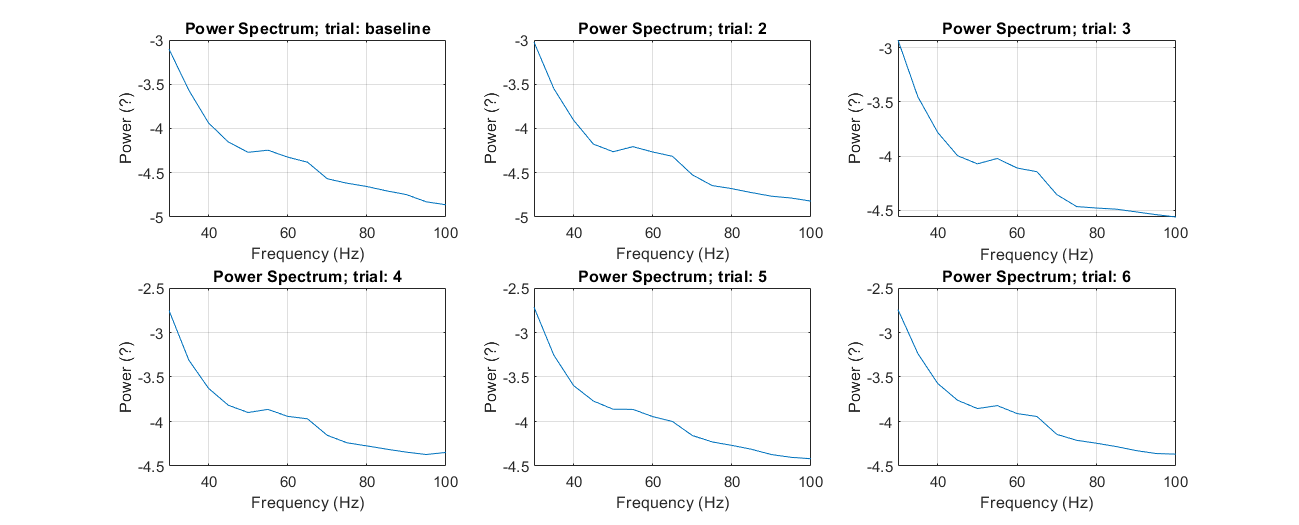

% Set full range of frequencies for all trials
for trial = 1:6
    if ismember(band, [delta, theta, alpha, beta])
        dat{trial}.freq=1:30;
    else
        dat{trial}.freq=30:5:100;
    end
end

% Plotting
fig2          = figure('position',[680 240 1039 420]); % Create new figure
for trial = 1:6
    subplot(2,3,trial);
    plot(dat{trial}.freq, squeeze(mean(mean(dat{trial}.powspctrm, 2), 1)));
    xlabel('Frequency (Hz)');
    ylabel('Power (?)');
    grid on;
    if band == delta
        if trial == 1
            title('Delta Power Spectrum; trial: baseline');
        else
            title(['Delta Power Spectrum; trial: ' num2str(trial)]);
        end
    end
    if band == theta
        if trial == 1
            title('Theta Power Spectrum; trial: baseline');
        else
            title(['Theta Power Spectrum; trial: ' num2str(trial)]);
        end
    end
    if band == alpha
        if trial == 1
            title('Power Spectrum; trial: baseline');
        else
            title(['Power Spectrum; trial: ' num2str(trial)]);
        end
    end
    if band == beta
        if trial == 1
            title('Beta Power Spectrum; trial: baseline');
        else
            title(['Beta Power Spectrum; trial: ' num2str(trial)]);
        end
    end
    if band == slowgamma
        if trial == 1
            title('Power Spectrum; trial: baseline');
            xlim([30 100])
        else
            title(['Power Spectrum; trial: ' num2str(trial)]);
            xlim([30 100])
        end
    end
    if band == fastgamma
        if trial == 1
            title('Fast Gamma Power Spectrum; trial: baseline');
        else
            title(['Fast Gamma Power Spectrum; trial: ' num2str(trial)]);
        end
    end
end